# Samples of a Population

# Group Assignment 9

## Test data 

Before software is tested on real data, it is tested with well-controlled test data. Test data is generated after a discrete stochastic process that has the following signal model:


$$X\left\lbrack n\right\rbrack =w\left\lbrack n\right\rbrack$$


where $w\left\lbrack n\right\rbrack$ is i.i.d and $w\left\lbrack n\right\rbrack ~N\left(7,2\right)$

w_var = 2;
w_mean = 7;

## Questions

1) Are the samples of X(n) statistically independent?

Yes because they are independent. (What does i.i.d mean??)

2) Is the process ergodic? 

Yes i think so, since the mean and variance are given for the process. Since it is given for the whole process,

it means that no matter hvis ensemble you choose you are able to tell something about the the whole process

from that ensemble alone, given the variance and mean. 

3) Plot the data from one realisation of the process.

Remember that the standard afvigelse is give by sqrt(var). So if we want to plot one realisation of the process

we do it like this, (don't quite follow, but randn returns a normally distributed vector of random numbers)

X_realization = sqrt(w_var) * randn(1,100) + 7

X_realization =     7.1734    9.4467    5.2571    3.5264    5.5263    5.3207    5.0125    6.0707    6.4529    8.9384    6.0799    6.4361    8.3138    8.6641    5.8156    7.2620    7.7564    4.7205    8.6112    8.6901    7.2413    4.0073    8.6032    5.7282    5.2466    5.3078    7.8529    5.7635    7.5079    9.1466    8.1254    5.7059    4.1471    5.8808    8.1445    6.6315    6.1022    7.8796    7.0136    7.7342    7.0853    7.4720    7.8250    9.6472    6.1810    6.8706    6.5008    8.6584    5.6016    7.7471


plot(X_realization)

4) What is the population in this case?

The population in this case is all the realizations of the process 

(In statistics, a population is a complete set of items that share at least one property in 

common that is the subject of a statistical analysis.)

But it coulve been a subgroup i think

5) Use the formula to calculate the sample mean. 


$$\mu^ˆ =\overset{-}{X} =\frac{1}{n}\sum_{i=1}^n X_i$$


sum = 0;
for i = 1: 100
    sum = sum + X_realization(i);
end

sample_mean = sum/100

sample_mean = 6.8304

6) Verify with the matlab function mean()

matlab_sample_mean = mean(X_realization)

matlab_sample_mean = 6.8304

7) Use the formula to calculate the sample variance.


$${\sigma^ˆ }^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(x_i -\mu^ˆ \right)}^2$$


sum_var = 0;
for i = 1 : 100
    sum_var = sum_var + power(X_realization(i) - sample_mean, 2);
end

formula_var = (1/(100-1)) * sum_var

formula_var = 2.3774

8) Verify with the matlab function var().

matlab_sample_var = var(X_realization)

matlab_sample_var = 2.3774

9) Find the z-score for the data. What does the z-score tell you?


$$z=\frac{\overset{-}{x} -\mu }{\frac{\sigma }{\sqrt{n}}}~N\left(\mu ,\sigma^2 \right)$$


formula_std_deviation = sqrt(formula_var);
z = ((sample_mean-w_mean)/(formula_std_deviation/sqrt(100)))

z = -1.0996

z_false = ((10-w_mean)/(formula_std_deviation/sqrt(100)))

z_false = 19.4569

z_if_true_match = ((7-w_mean)/(sqrt(2)/sqrt(100)))

z_if_true_match = 0

z indexet fortæller noget om hvor godt passer den realization/model til det reele data. Jo tættere på 0

jo bedre, og som det også kan ses ovenover, hvis middelværdien og variancen stemmer helt overens med 

de reele værdier, så får man altså z-indekset til at være 0. Så z-indekset kan man sige fortæller hvor godt 

den model der er udvalgt med de værdier for middelværdi og varians, passer med de reele værdier.

10) Find the confidence interval for the mean (lower and upper endpoint).

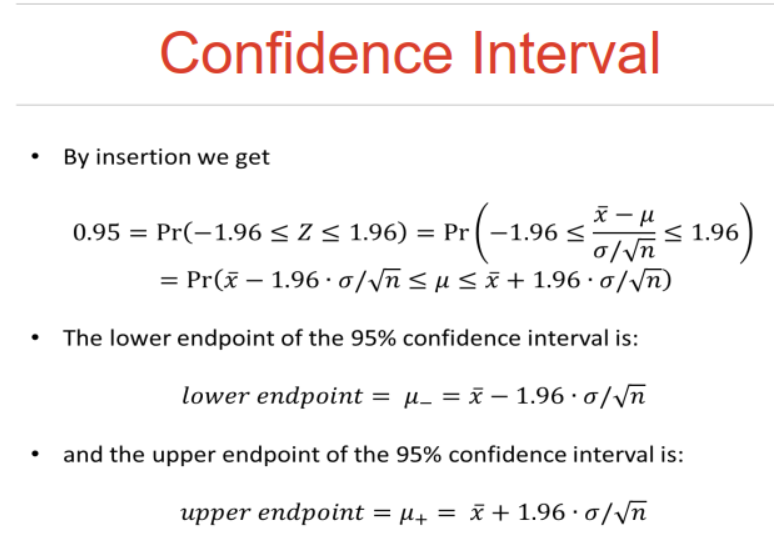

lower_bound = sample_mean - norminv(0.975) * (formula_std_deviation/sqrt(100))

lower_bound = 6.5282

upper_bound = sample_mean + norminv(0.975) * (formula_std_deviation/sqrt(100))

upper_bound = 7.1327

11) Draw the confidence interval on the plot together with the data. What does the confidence interval tell you?

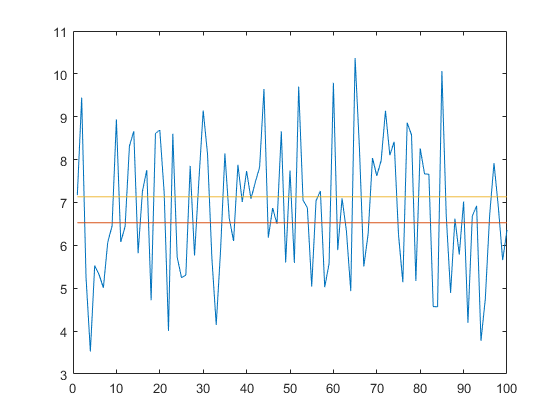

hold on
plot((ones(1, 100)).*lower_bound)
hold on
plot((ones(1, 100)).*upper_bound)

In 95% of the cases, the true mean mu wil lie between the endpoints calculated from the sample mean, but in 5% cases it will not

12) How large a sample size do you actually need?

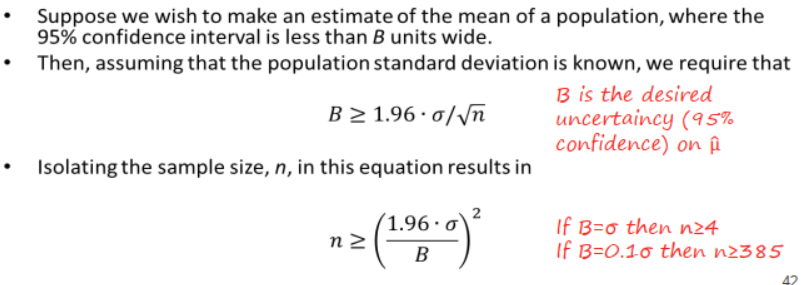

B = norminv(0.975)*(formula_std_deviation/sqrt(100))

B = 0.3022

% Set Uncertainty. The more precice, the more tests/sample size are/is needed
B = 0.15

B = 0.1500

n = power(((norminv(0.975)*formula_std_deviation)/B), 2)

n = 405.8917

13) Repeat questions 3 and 6, 30 times and make a histograms of the found sample means. What distribution do the samples have?

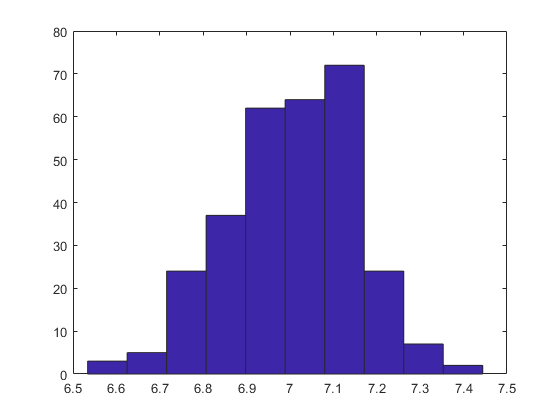

%meansX = zeros(300);
for nn = 1 : 30
    temp_real = sqrt(w_var) * randn(1,100) + w_mean;
    meansX(nn) = mean(temp_real);
end
figure(2)
hist(meansX)

14) fatter ikke denher?